clc;
clear all;
close all;

run("Q310_Basic.mlx")

sys_dis_open =
 
   0.1604 z^2 - 0.1958 z + 0.07861
  ----------------------------------
  z^3 - 1.937 z^2 + 1.122 z - 0.1421
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



c =          0    0.1604   -0.1958    0.0786


d =     1.0000   -1.9367    1.1220   -0.1421


sys_cont_close =
 
     7.8 s^3 + 205.7 s^2 + 601.4 s + 1276
  -------------------------------------------
  s^4 + 15.8 s^3 + 212.7 s^2 + 608.4 s + 1276
 
Continuous-time transfer function.


sys_dis_close =
 
  0.1328 z^3 - 0.3505 z^2 + 0.3048 z - 0.08705
  --------------------------------------------
  z^4 - 3.73 z^3 + 5.24 z^2 - 3.288 z + 0.778
 
Sample time: 0.015887 seconds
Discrete-time transfer function.



c1 =          0    0.1328   -0.3505    0.3048   -0.0871


d1 =     1.0000   -3.7296    5.2395   -3.2878    0.7780


## generate data

tfinal=100;
t = 0:T_s_close:tfinal;

Priemss=primes(100);
u=zeros(numel(t),1);
for i=20:numel(Priemss)
    input_dummy=gensig('sine' , tfinal/Priemss(1,i) , tfinal ,T_s_close);
    u=u+input_dummy;
end

var_e=0.7;
e=sqrt(var_e);
Noise=(-e+(e+e)*rand(numel(t),1));
u=u+Noise;
y = lsim(sys_dis_close ,u ,t);


### smooth parameter variation 

paras=[];
uu=400

uu = 400

for temp=uu:numel(y)
    paras(:,temp)=[d1(2:end)+d1(2:end)*.001*(sin(.005*(temp-uu))),(c1+c1*.001*(sin(.005*(temp-uu))-1))]';
    y(temp)=[-(y(temp-1:-1:temp-4))',(u(temp:-1:temp-4))']*paras(:,temp);
end

    sys_dis = tf(c1+c1*.0001*(sin(.05*(temp-uu))-1)' ,[1 -d1(2:end)+d1(2:end)*.0001*(sin(.05*(temp-uu)))'], T_s)

sys_dis =
 
  0.1328 z^3 - 0.3504 z^2 + 0.3048 z - 0.08704
  --------------------------------------------
  z^4 + 3.73 z^3 - 5.24 z^2 + 3.288 z - 0.7781
 
Sample time: 0.24388 seconds
Discrete-time transfer function.



    ident_analog = d2c(sys_dis)

ident_analog =
 
    -0.4281 s^4 + 6.619 s^3 + 1.974 s^2 - 29.16 s + 0.443
  ----------------------------------------------------------
  s^5 - 5.515 s^4 + 141.1 s^3 + 1229 s^2 + 5790 s + 1.238e04
 
Continuous-time transfer function.



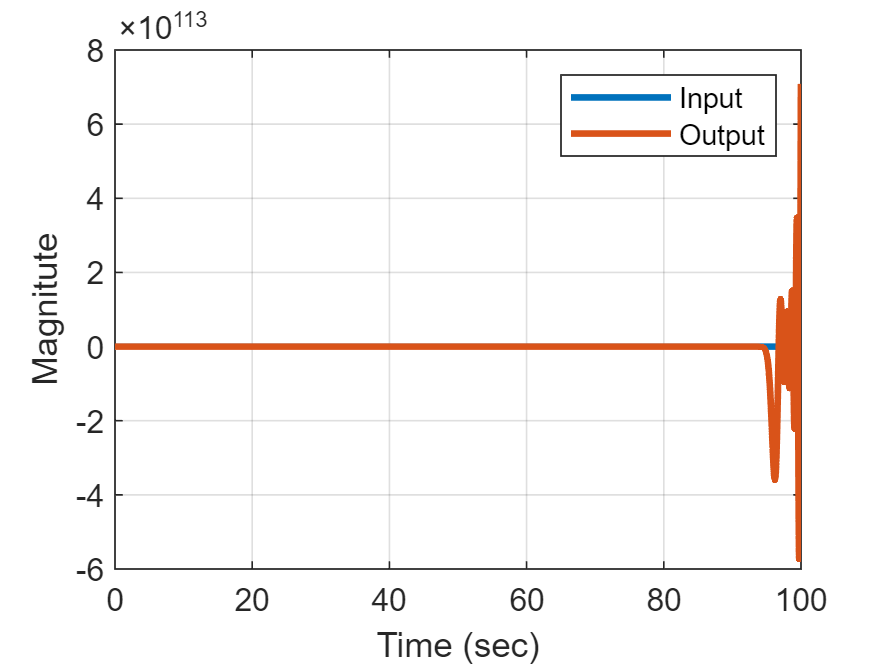


plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitute') ;
grid on
legend('Input','Output') ;

## Kalman Filter

N = numel(y) ;
% %--------------------------%
%choose number of parameters
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

% %--------------------------%
Nv=Parameters_in_num+Parameters_in_den;

p_KF(1:Nv,1:Nv,1:N)=zeros(Nv,Nv,N);
%intitial Conditions
theta_hat_KF(1:Nv,1:N)=ones(Nv,N);
K_KF(1:Nv,1:N)=zeros(Nv,N);
var_e=0.05;

p_KF(1:Nv,1:Nv,1)=1e5*eye(Nv);p_KF(1:Nv,1:Nv,2)=p_KF(1:Nv,1:Nv,1);p_KF(1:Nv,1:Nv,3)=p_KF(1:Nv,1:Nv,2);


for i=(max(Parameters_in_num,Parameters_in_den)+1):N
    phi_KF(:,i)         =[(y(i-1:-1:i-Parameters_in_den))',(u(i-1:-1:i-Parameters_in_num))']';
    K_KF(:,i)           =p_KF(:,:,i-1)*phi_KF(:,i)*(1+phi_KF(:,i)'*p_KF(:,:,i-1)*phi_KF(:,i))^(-1) ;  
    p_KF(:,:,i)         =p_KF(:,:,i-1)-p_KF(:,:,i-1)*phi_KF(:,i)*(1+phi_KF(:,i)'*p_KF(:,:,i-1)*phi_KF(:,i))^(-1)*phi_KF(:,i)'*p_KF(:,:,i-1)+var_e;
    theta_hat_KF(:,i)   =theta_hat_KF(:,i-1)+K_KF(:,i)*(y(i)-phi_KF(:,i)'*theta_hat_KF(:,i-1));
end


Bode

ident_dis = tf(theta_hat_KF((Parameters_in_num+1):end,end)' ,[1 -theta_hat_KF(1:Parameters_in_num ,end)'], T_s_close)

ident_dis =
 
   0.1306 z^2 - 0.2329 z + 0.09364
  ---------------------------------
  z^3 - 2.832 z^2 + 2.682 z - 0.845
 
Sample time: 0.015887 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
     7.747 s^2 + 160 s - 2359
  -------------------------------
  s^3 + 10.6 s^2 + 45.52 s + 1289
 
Continuous-time transfer function.



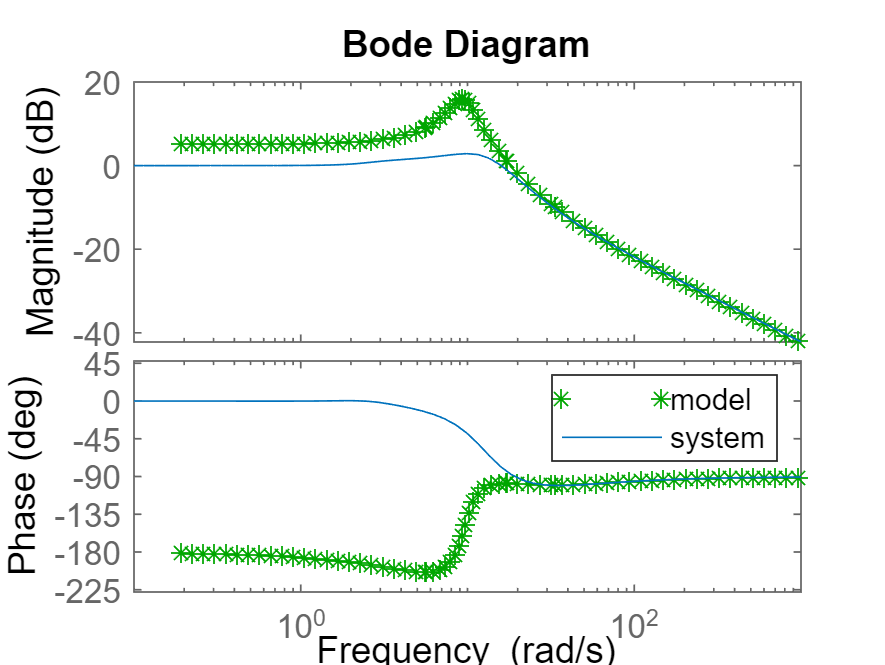

bode(ident_analog ,'g*',sys_cont_close )
legend('model ','system')

KF Convergence

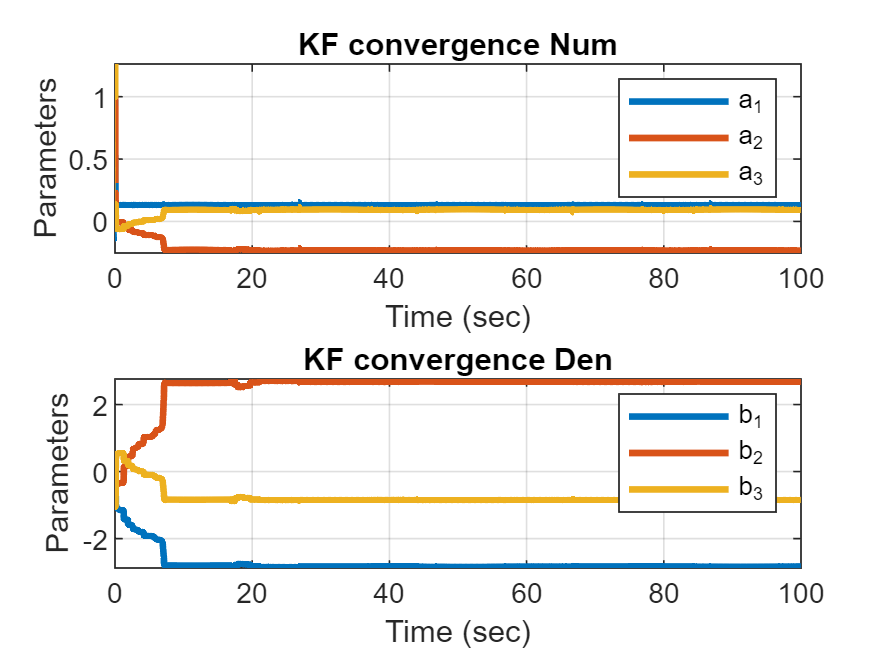

subplot(2,1,1)
plot(t , theta_hat_KF((Parameters_in_num+1):end,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('KF convergence Num') ;
grid on
legend('a_1','a_2','a_3')
% xlim([0 6])
% ylim([-1 1])
%--------------------------------------------------------------
subplot(2,1,2)
plot(t , -theta_hat_KF(1:Parameters_in_num ,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('KF convergence Den') ;
grid on
legend('b_1','b_2','b_3')

% xlim([0 6])
% ylim([-7  7])
